# Radar Equation

- [https://www.rfcafe.com/references/electrical/ew-radar-handbook/one-way-radar-equation.htm](https://www.rfcafe.com/references/electrical/ew-radar-handbook/one-way-radar-equation.htm)

- [https://www.rfcafe.com/references/electrical/ew-radar-handbook/two-way-radar-equation.htm](https://www.rfcafe.com/references/electrical/ew-radar-handbook/two-way-radar-equation.htm)

clear;
clc;

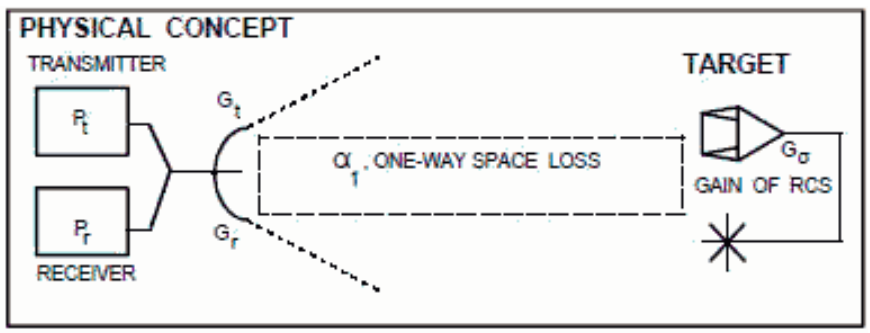

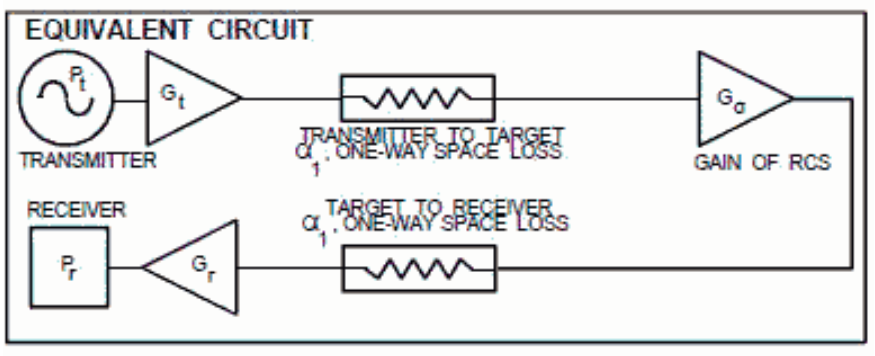

- Settings

fc      = 2.4e9;
c       = physconst("LightSpeed");
lambda  = freq2wavelen(fc,c)

lambda = 0.1249

- Target

R   = 40e3;
RCS = 10.0;

### Transmitter

Pt_lin      = 1470;  % W   % 1470
Pt_dBW      = 10*log10(Pt_lin)

Pt_dBW = 31.6732

### Tx Antenna

Gt_dB       = 27.56; % dBi
Gt_lin      = power(10,Gt_dB/10)

Gt_lin = 570.1643

### RX

rxGain  = 30.0; 
NF      = 6.0;

EIRP = Pt_dBW + Gt_dB

EIRP = 59.2332

alpha1_dB = 10*log10((lambda^2)/((4*pi*R)^2))

alpha1_dB = -132.0932

P1 = EIRP+alpha1_dB

P1 = -72.8600

- Target "gain"

Gtgt = (4*pi*RCS)/(lambda^2)

Gtgt = 8.0536e+03

Gtgt_dB = 10*log10(Gtgt)

Gtgt_dB = 39.0599

P2 = P1+Gtgt_dB

P2 = -33.8001

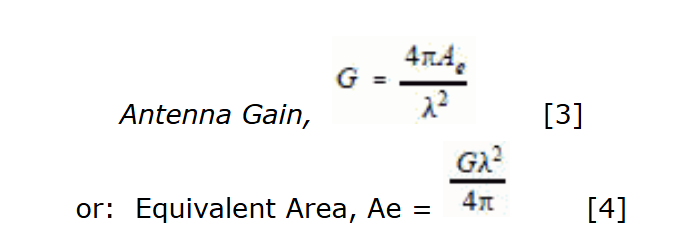


$$\Pr =\textrm{PtGt}\;x\;\frac{\lambda^2 }{4\textrm{pi}{\mathrm{R}}^2 }\;x\;4\frac{\textrm{pisigma}}{\lambda^2 }\;x\;\frac{\textrm{Gr}\;\lambda^2 }{4\textrm{piR2}}$$


P3 = P2 + alpha1_dB

P3 = -165.8933

P4 = P3 + Gt_dB

P4 = -138.3333

P5 = P4 + (rxGain - NF)

P5 = -114.3333

(Pt_dBW + Gt_dB) + alpha1_dB + Gtgt_dB + Gt_dB + alpha1_dB

ans = -138.3333

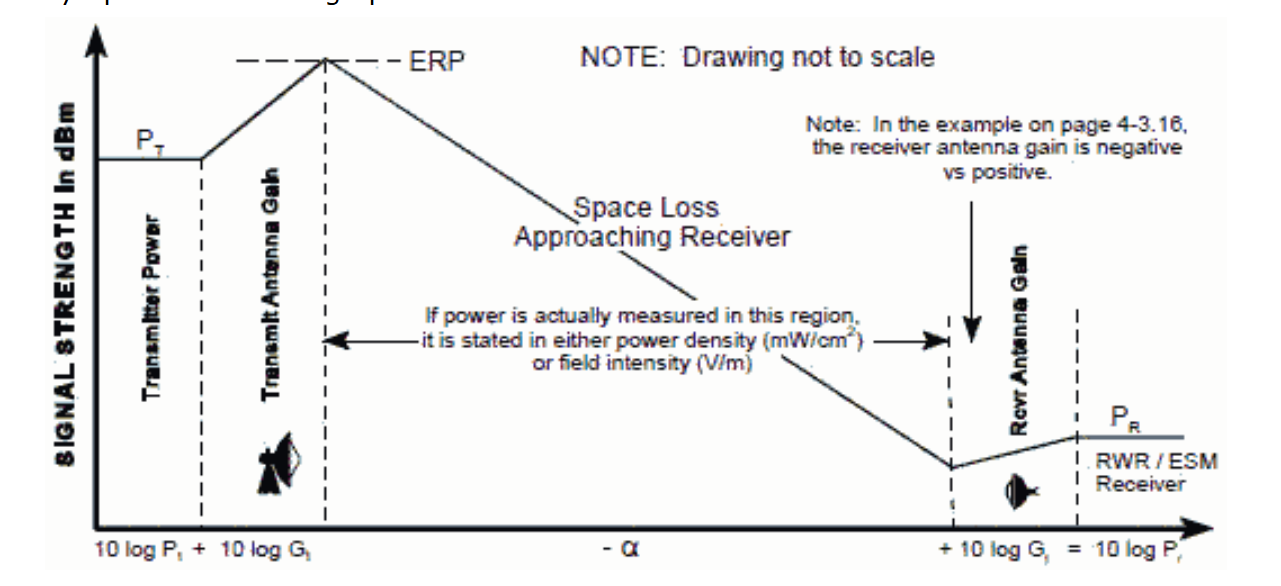

y = [Pt_dBW, EIRP,P1, P2]

y =    31.6732   59.2332  -72.8600  -33.8001


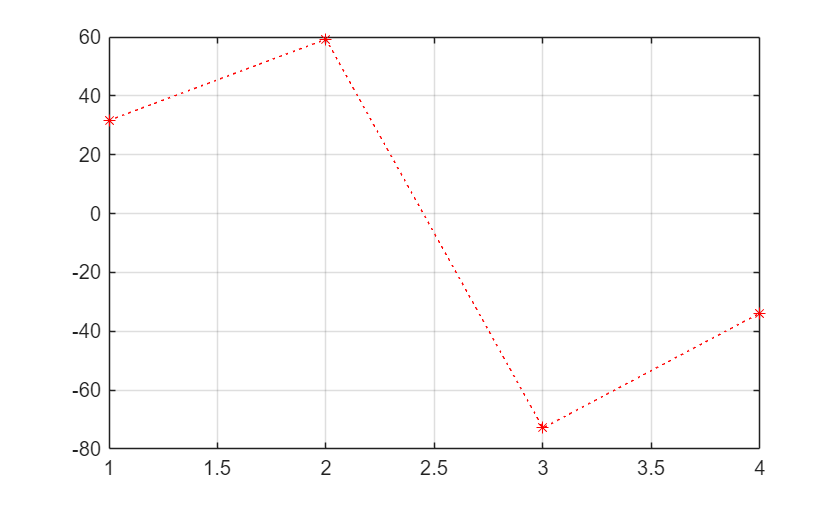

figure
plot(y,'r:*')
grid on

Example of One-Way Signal Strength: A 5 (or 7) GHz radar has a 70 dBm signal fed through a 5 dB loss

transmission line to an antenna that has 45 dB gain. An aircraft that is flying 31 km from the radar has an aft EW antenna with -1 dB gain and a 5 dB line loss to the EW receiver (assume all antenna polarizations are the same).

Note: The respective transmission line losses will be combined with antenna gains, i.e.:

-5 +45 = 40 dB, -5 - 1 = -6 dB, -10 + 5 = -5 dB.

(1) What is the power level at the input of the EW receiver?

Answer (1): Pr at the input to the EW receiver = Transmitter power - xmt cable loss + xmt antenna gain - space loss + rcvr antenna gain - rcvr cable loss.

Space loss (from section 4-3) @ 5 GHz = 20 log f R + K1 = 20 log (5x31) + 92.44 = 136.25 dB.

Therefore, Pr = 70 + 40 - 136.25 - 6 = -32.25 dBm @ 5 GHz (Pr = -35.17 dBm @ 7 GHz since α1 = 139.17 dB)

(2) If the received signal is fed to a jammer with a gain of 60 dB, feeding a 10 dB loss transmission line which is connected to an antenna with 5 dB gain, what is the power level from the jammer at the input to the receiver of the 5 (or 7) GHz radar?

Answer (2): Pr at the input to the radar receiver = Power at the input to the EW receiver+ Jammer gain - jammer cable loss + jammer antenna gain - space loss + radar rcvr antenna gain - radar rcvr cable loss .

Therefore, Pr = -32.25 + 60 - 5 - 136.25 + 40 = -73.5 dBm @ 5 GHz. (Pr = -79.34 dBm @ 7 GHz since

α1 = 139.17 dB and Pt = -35.17 dBm).

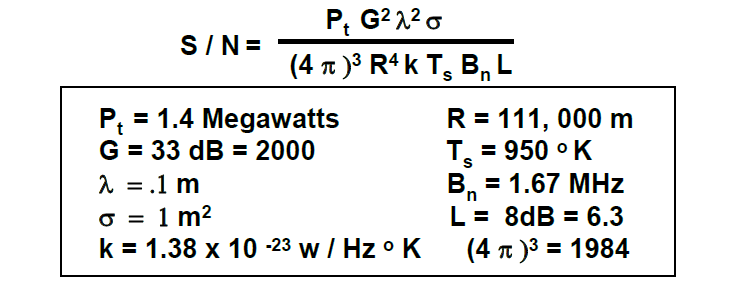

exPt = 10*log10(txPowerWatts)
exG = antennaGaindB
exLambda = abs((10*log10(lambda))*2)
exSigma = 10*log10(10)
exR = 10*log10(refRange)*4
exK = -10*log10(k)
exT = 10*log10(T)
exLosses = abs(0);
exBW     = 10*log10(1.0e6)
P = exPt + (2*exG) + exSigma + exK
M = exLambda + 33 + exR + exT + exLosses + exBW
margin = P-M
exIntGain = 10*log10(N)
margin = margin+exIntGain